# Battery testing, modelling, and state estimation - SOH estimation seminar

*David Vošahlík, Tomáš Haniš*

Battery State of Healt (SOH) online estimation will be today's main target. It is one of the most studied battery parameters, which is, unfortunatelly, not measurable directly. It is usually represented by battery capacity, internal resistance change or their combination. The change of these parameters is caused by the battery cell aging and it has to be estimated. There are many methods ranging from very simple ones like various lookup tables based on the cycles count up to more advanced model-based methods like Kalman Filter (KF) algorithm or its non-linear versions such as Extended Kalman Filter (EKF) or Unscented Kalman FIlter (UKF). 

In our case SOH will be equal to the capacity. Therefore, the SOH estimation is reduced just to capacity estimation.

## EKF SOH estimation method

There are various methods for the SOH estimation. We will leverage the last seminar solution to the SOC estimation and add one additional EKF to estimate the battery parameter - capacity. This approach is called dual estimation.

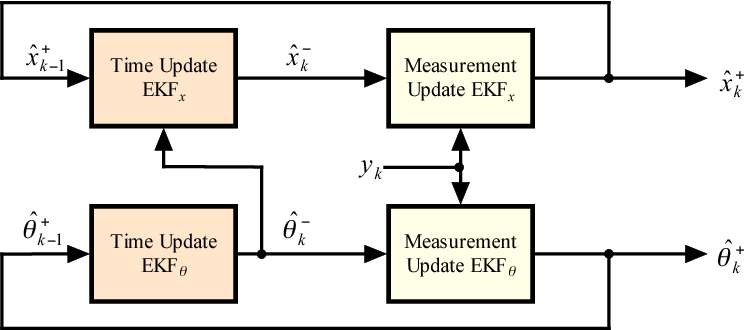

Another approach is the so called joint estimation, where everything is estimated in one EKF. 

In both approaches the capacity is represented as additional state of the model for the EKF. It has no modelled dynamics (it is just a constant). The change of the capacity is represented by the process noise matrix Q.


$$\begin{array}{l}
\dot{C} =0\\
C\left(t+1\right)=C\left(t\right)
\end{array}$$


Third option is to modify the model according to your needs. In case of the battery SOH estimation, we want the capacity to be really slowly changing. We can express this requirement in the model by adding 2 states:


$$\begin{array}{l}
\dot{C} =\frac{1}{\tau \;}\left(C_{\textrm{in}} -C\right)\\
\dot{\;C_{\textrm{in}} } =0
\end{array}$$


where the $\tau$ is time constant, where the required behavior can be set.

### SOH estimation task

In this seminar, you will implement the dual EKF (two EKFs - one for SOC and one for SOH). It will be done on the seminar and it will be also your homework.

The SOC estimator is ready for you below from the previous seminar.

%Implement SOH estimation
set(groot, 'defaultTextInterpreter', 'latex')
export_figures = false;

### SOC estimation

#### 2RC model data

Use the measured data to run and validate the estimation

% The model input is current i, assume only the 25 deg C temperature (3rd row in the parameters)
Bat = InitializeBatPars();              % Setup the constants
% Load the measured data
[Time, Current, Voltage, SoC_ref, Capacity] = load_data();

%[pks, peak_locs] = findpeaks(SoC_ref, MinPeakProminence=2, MinPeakHeight=85);
[~, peak_locs] = findpeaks(-SoC_ref, MinPeakProminence=10, MinPeakHeight=-35);
%peak_locs = [1 peak_locs];
assert(numel(peak_locs) == numel(Capacity));

Verify that the reference data match the model

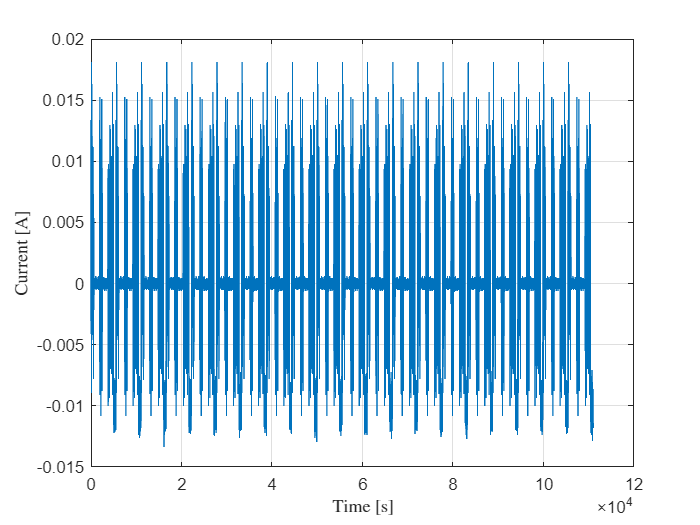

plot(Time, Current);
xlabel('Time [s]');
ylabel('Current [A]');
grid on;

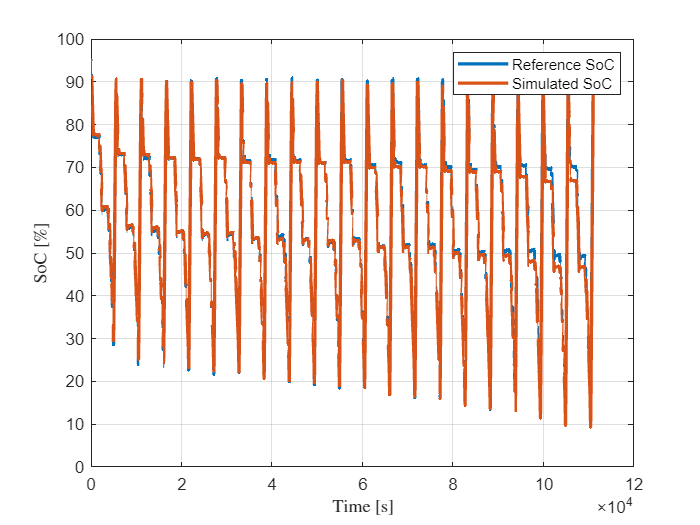

Ts = 0.1; % Sampling period

n = 3; % Three states
m = 1; % One input
p = 1; % One output
N = length(Time); % Number of samples

u = Current;
y = Voltage;

x_sim = zeros(n, N);
y_sim = zeros(p, N);

x_sim(:, 1) = [0;0; SoC_ref(1)]; % Set the correct initial condition

% Verify that signals match the model
for k = 1:N-1
    if find(k == peak_locs)
        Bat.C = Capacity(k == peak_locs) / 1e3;
    end
    % Forward Euler discretization ... x_next = x + Ts * f(x, u)
    % f is the continuous time state derivative function
    x_sim(:, k+1) = x_sim(:, k) + Ts * f_Bat(x_sim(:, k), u(:, k), Bat);
    y_sim(:, k) = g_Bat(x_sim(:, k), u(:, k), Bat);
end
y_sim(:, N) = g_Bat(x_sim(:, N), u(:, N), Bat);

plot(Time, [SoC_ref; x_sim(3, :)], linewidth=2);
xlabel('Time [s]');
ylabel('SoC [\%]');
legend('Reference SoC', 'Simulated SoC')
grid on;

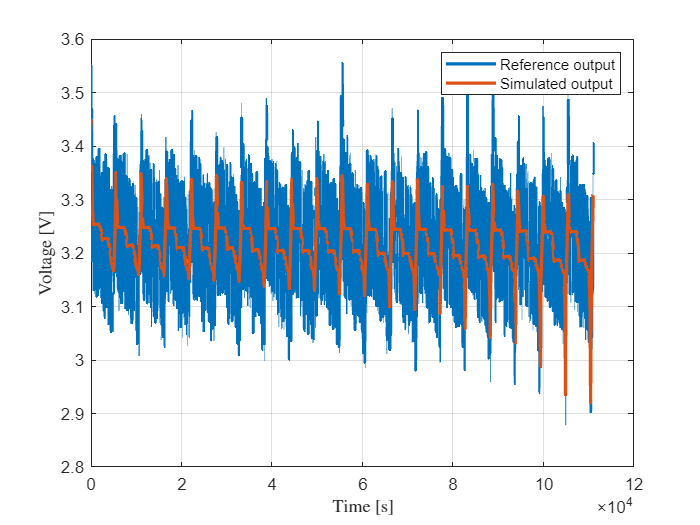

if export_figures
    exportgraphics(gcf, "figures/validation-soc.eps");
end
plot(Time, [y; y_sim], linewidth=2);
xlabel('Time [s]');
ylabel('Voltage [V]');
legend('Reference output', 'Simulated output')
grid on;

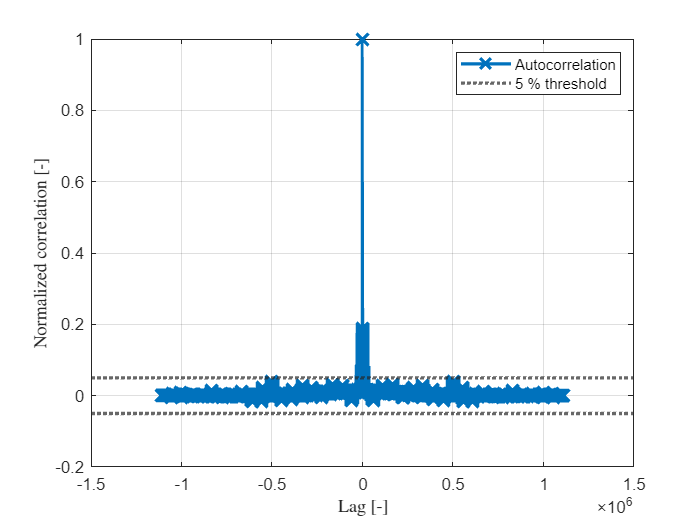

if export_figures
    exportgraphics(gcf, "figures/validation-U.eps");
end
y_noise = y - y_sim;
[c, lags] = xcorr(y_noise);
xcorr_peak = c(lags == 0);
plot(lags, c / xcorr_peak, linewidth=2, Marker="x", MarkerSize=10);
hold on;
yline([-1 1] * 5e-2, ':', linewidth=2);
legend('Autocorrelation', '', '5 % threshold')
hold off
xlabel('Lag [-]');
ylabel('Normalized correlation [-]')
grid on
if export_figures
    exportgraphics(gcf, "figures/validation-pred-error.eps");
end
a1 = gca;
fig = figure;
a2 = copyobj(a1, fig);

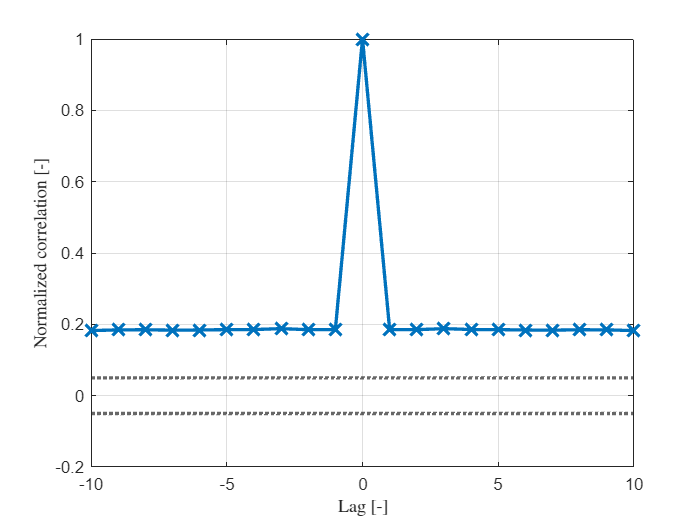

xlim([-10 10])

if export_figures
    exportgraphics(fig, "figures/validation-pred-error-detail.eps");
end

#### EKF implementation

Your second task will be to implement the EKF. EKF has two essential parts. There is a data step and time step. The data step is defined as:


$$\begin{array}{l}
\hat{x} \left(t|t\right)=\hat{x} \left(t|t-1\right)+P\left(t|t-1\right)C^T \left(t\right){\left(C\left(t\right)P\left(t|t-1\right)C^T \left(t\right)+R\right)}^{-1} \left(y\left(t\right)-g\left(\hat{x} \left(t|t-1\right),u\left(t-1\right)\right)\right)\\
P\left(t|t\right)=P\left(t|t-1\right)-P\left(t|t\right)C^T \left(t\right){\left(C\left(t\right)P\left(t|t-1\right)C^T \left(t\right)+R\right)}^{-1} C\left(t\right)P\left(t|t-1\right)
\end{array}$$


The data step is also sometimes called the correction step

Then, the time step is defined as:


$$\begin{array}{l}
\hat{x} \left(t+1|t\right)=f\left(\hat{x} \left(t|t\right),u\left(t\right)\right)\\
P\left(t+1|t\right)=A\left(t\right)P\left(t\right)A^T \left(t\right)+Q
\end{array}$$


where the system matrices A and C (sometimes called jacobians) are defined as:


$$A\left(t\right)=\frac{\partial f\left(\hat{x} \left(t|t\right),u\left(t\right)\right)}{\partial x},\;\;C\left(t\right)=\frac{\partial g\left(\hat{x} \left(t|t-1\right),u\left(t\right)\right)}{\partial x}$$
 

To sum up. Implement 3 basic things:

- data step

- time step

- jacobians

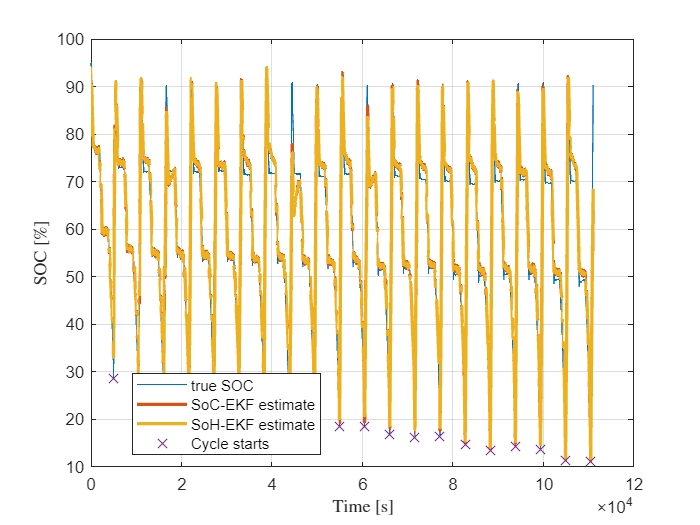

Bat = InitializeBatPars(); % Reinitialize battery to correct any changes done during verification
% Implement EKF SOC estimation method
SOC0 = SoC_ref(1);
% Define the initial state for EKF
xhat_soc = zeros(3, numel(Time));
xhat_soh = zeros(2, numel(Time));
% Shift the initial estimated SOC -> The initial state is not known perfectly
xhat_soc(:, 1) = [0;0; SOC0 - 15];
xhat_soh(:, 1) = [3; 80]; % Nominal capacity and charge

% Define and tune the Q and R matrices used in the EKF
Q_soc = diag([0.00001, 0.0001, 3]) / 100;
R_soc = 0.05; % 5 worked like a charm

Q_soh = diag([1e-8 1e-10]);
R_soh = 1;
% Setup the initial covariance matrix
P_soc = Q_soc*5000;
P_soh = Q_soh*5000;

Ts = mean(diff(Time)); % 0.1 s

% Initialize the output vector
yhat_soc = zeros(1, numel(Time));
yhat_soh = zeros(1, numel(Time));

for k=1:length(Time)
    % SoC EKF
    % Data step EKF
    C = dgdx_Bat(xhat_soc(:, k));                                                     % matrix C(t) approx
    L = P_soc*C'/(C*P_soc*C' + R_soc);                                              % kalman gain for data step
    P_soc = P_soc - L*(C*P_soc*C' + R_soc)*L';                                          % P(t|t) estimate
    yhat_soc(:, k) = g_Bat(xhat_soc(:, k), Current(k), Bat);                     % Compute the estimated output
    e = Voltage(k) - yhat_soc(:, k);
    xhat_soc(:, k) = xhat_soc(:, k) + L * e;% xhat(t|t) estimate

    if k < length(Time)
        %Time step
        A = dfdx_Bat(xhat_soc(:, k), Current(k), Bat, Ts);                                % matrix A(t) approx
        xhat_soc(:, k + 1) = xhat_soc(:, k) + Ts * f_Bat(xhat_soc(:, k), Current(k), Bat);         % xhat(t+1|t) estimate
        P_soc = A*P_soc*A' + Q_soc;                                                     % P(t+1|t) estimate
    end

    % SoH EKF
    % Data step EKF
    C = dgdx_Soh(xhat_soh(:, k));                                                     % matrix C(t) approx
    L = P_soh*C'/(C*P_soh*C' + R_soh);                                              % kalman gain for data step
    P_soh = P_soh - L*(C*P_soh*C' + R_soh)*L';                                          % P(t|t) estimate
    yhat_soh(:, k) = g_Soh(xhat_soh(:, k), Current(k), Bat);                     % Compute the estimated output
    e = xhat_soc(3, k) - yhat_soh(:, k);
    xhat_soh(:, k) = xhat_soh(:, k) + L * e;% xhat(t|t) estimate

    Ts_soh = Ts;
    %Time step
    if k < length(Time)
        A = dfdx_Soh(xhat_soh(:, k), Current(k), Bat, Ts_soh);                                % matrix A(t) approx
        xhat_soh(:, k + 1) = xhat_soh(:, k) + Ts_soh * f_Soh(xhat_soh(:, k), Current(k), Bat);         % xhat(t+1|t) estimate
        P_soh = A*P_soh*A' + Q_soh;                                                     % P(t+1|t) estimate
    end
    Bat.C = xhat_soh(1, k);
end

% Plot the comparison of estimated and actual SOC
figure();
clf;
plot(Time, SoC_ref);
hold on;
plot(Time, [xhat_soc(3, :); xhat_soh(2, :)], 'LineWidth', 2);
plot(Time(peak_locs), SoC_ref(peak_locs), 'x', MarkerSize=8)
grid on;
xlabel('Time [s]');
ylabel('SOC [\%]');
legend('true SOC', 'SoC-EKF estimate', 'SoH-EKF estimate', 'Cycle starts', location='best');
hold off

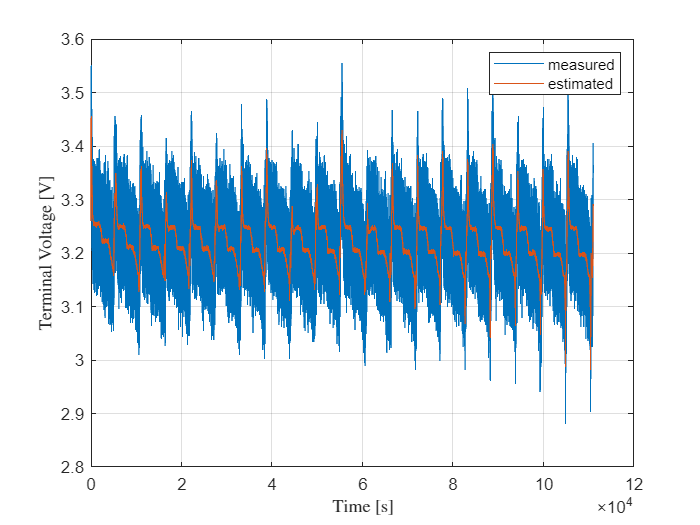

if export_figures
    exportgraphics(gcf, "figures/soc-estimate.eps");
end
% Plot the comparison of estimated and actual output
figure();
clf;
plot(Time, Voltage);
hold on;
plot(Time, yhat_soc);
grid on;
xlabel('Time [s]');
ylabel('Terminal Voltage [V]');
legend('measured', 'estimated');

if export_figures
    exportgraphics(gcf, "figures/voltages.eps");
end

rms(SoC_ref - xhat_soc(3, :))

ans = 3.4138

rms(SoC_ref - xhat_soh(2, :))

ans = 3.4189

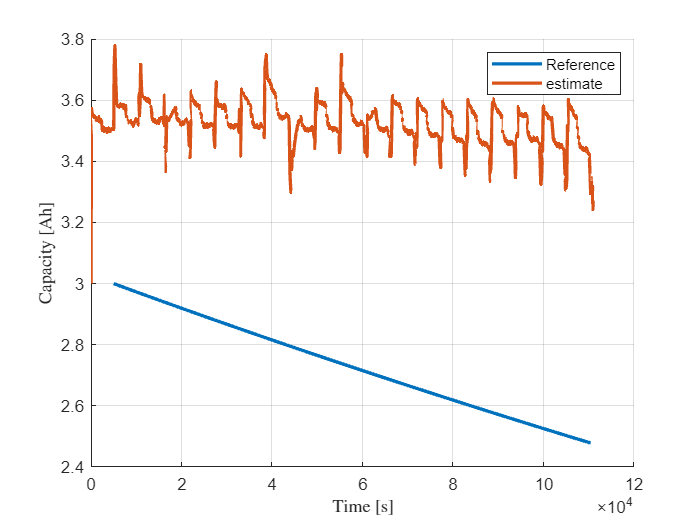

% Plot the comparison of capacity
figure();
clf;
hold on;
plot(Time(peak_locs), Capacity / 1e3, LineWidth=2);
plot(Time, xhat_soh(1, :), LineWidth=2);
grid on;
xlabel('Time [s]');
ylabel('Capacity [Ah]');
legend('Reference', 'estimate');

if export_figures
    exportgraphics(gcf, "figures/capacity-estimate.eps");
end

function [y_bat] = g_Bat(bat_state, u_bat, Bat)
% output function for battery - continuous time dynamics
% x_bat - is the battery state [U1 [V], U2 [V], SOC [%]]
% u_bat - is the battery input [Current [A]]
% y_bat - is the battery output [Terminal voltage [V]]
% car - structure with the parameters. Check InitializeCar.m function

% Compute the terminal voltage output. Use the constants defined in the car.Bat
y_bat = ocv(bat_state(3)) - bat_state(1) - bat_state(2) - u_bat*Bat.R0;
end

function C = dgdx_Bat(x,u,Bat)
% Compute the discrete time jacobian of the output function with respect to state (system matrix C)

% Copmute the continuous time matrix C. It is the same as the discrete time one
SOC = x(3);
ocvDx =  0.09131 - 2*0.003962*SOC + 3*8.231e-05*SOC^2 - 4*8.089e-07*SOC^3 + 5*3.036e-09*SOC^4;
C = [-1 -1 ocvDx]; 
end

function [xDot_bat] = f_Bat(bat_state, u_bat, Bat)
% State derivative function for battery - continuous time dynamics
% x_bat - is the state [U1 [V], U2 [V], SOC [%]]
% u_bat - is the input [Current [A]]
% car - structure with the parameters. Check InitializeCar.m function

% Implement the continuous time dynamic equations. Use the constants defined in the car.Bat
U1_dot = -1/(Bat.R1*Bat.C1)*bat_state(1) + 1/Bat.C1*u_bat(1);
U2_dot = -1/(Bat.R2*Bat.C2)*bat_state(2) + 1/Bat.C2*u_bat(1);

if u_bat(1) > 0
    eta = 1;
else
    % Charging
    eta = Bat.eta;
end

SOC_dot = -eta/(Bat.C/36)*u_bat(1);

% Sort the derivative values to the vector
xDot_bat = [U1_dot;U2_dot;SOC_dot];
end

function A = dfdx_Bat(x, u, Bat, Ts)
% Compute the discrete time jacobian of the system derivative function with respect to state (system matrix A)

% Compute the continuous time matrix A
a11 = -1/(Bat.R1*Bat.C1);
a22 = -1/(Bat.R2*Bat.C2);
Ac = diag([a11, a22, 0]);
% Discretize the matrix A
A = expm(Ac*Ts);
end

function [y] = g_Soh(x, u, Bat)
% output function for SoH model - continuous time dynamics
% x - is the SoH model state [C [Ah], SoC [%]]
% u - is the SoH model input [Current [A]]
% y - is the SoH model output [SoC [%]]

y = x(2);
end

function C = dgdx_Soh(x,u,Bat)
% Compute the discrete time jacobian of the output function with respect to state (system matrix C)

% Copmute the continuous time matrix C. It is the same as the discrete time one
C = [0 1]; 
end

function [xDot] = f_Soh(x, u, Bat)
% State derivative function for battery - continuous time dynamics
% x - is the SoH model state [C [Ah], SoC [%]]
% u - is the SoH model input [Current [A]]

if u(1) > 0
    eta = 1;
else
    % Charging
    eta = Bat.eta;
end


% Implement the continuous time dynamic equations. Use the constants defined in the car.Bat
C_dot = 0;
SoC_dot = -eta/(x(1)/36)*u(1);


% Sort the derivative values to the vector
xDot = [C_dot; SoC_dot];
end

function A = dfdx_Soh(x, u, Bat, Ts)
% Compute the discrete time jacobian of the system derivative function with respect to state (system matrix A)
% x - is the SoH model state [C [Ah], SoC [%]]
% u - is the SoH model input [Current [A]]
% Compute the continuous time matrix A

if u(1) > 0
    eta = 1;
else
    % Charging
    eta = Bat.eta;
end

Ac = [0, 0; eta * 36 / x(1)^2, 0];
% Discretize the matrix A
A = expm(Ac*Ts);
end

function Bat = InitializeBatPars()

% Battery parameters
Bat.eta = 0.977; % Added by VoMi to fix data sucking hard
Bat.R1 = 0.045;
Bat.R2 = 0.13;
Bat.C1 = 180;
Bat.C2 = 1790;
% capacity [Ah]
Bat.C_nominal = 3;
Bat.C = Bat.C_nominal;
% internal resistance [Ohm]
Bat.R0 = 0.0013;
end

function voltage = ocv(SOC)
% Copmute the open circuit voltage [V] for the provided SOC [%]
voltage = 2.353 + 0.09131*SOC - 0.003962*SOC^2 + 8.231e-05*SOC^3 - 8.089e-07*SOC^4 + 3.036e-09*SOC^5;
end



function dxdt = myode(t,x,ut,u, fun)
% function wrapper for the ode45 solver so that it is able to solve the differential equations
uInterp = zeros(size(u, 1), 1);
for i = 1:size(u, 1)
    uInterp(i) = interp1(ut,u(i,:),t); % Interpolate the data set (ut,u) at time t
end
dxdt = fun(x, uInterp); % Evaluate ODE at time t
end

function [Time, Current, Voltage, SoC, Capacity] = load_data()
data = load("SOH_Estimation_Data.mat");
Time = data.timeMeas;
Current = data.CurrentMeas;
Voltage = data.trmVoltMeas;
SoC = data.x_bat;
Capacity = data.Battery_C;
end